# Comparación de controladores discretos


$$G_p \left(z\right)=\frac{0\ldotp 4758}{z-0\ldotp 9048}z^{-2}$$


T = 1

T = 1

z = tf('z',T);
Gpz = 0.4758/(z-0.9048)*z^-2

Gpz =
 
       0.4758
  ----------------
  z^3 - 0.9048 z^2
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


step(Gpz)

theta = 2; % T = 1, d = 2
Gz = 0.4758/(z-0.9048);
Gs = d2c(Gz, 'zoh')

Gs =
 
    0.5
  -------
  s + 0.1
 
Continuous-time transfer function.
Model Properties


Gps = tf([0.5],[1,0.1],'inputdelay',theta)

Gps =
 
                0.5
  exp(-2*s) * -------
              s + 0.1
 
Continuous-time transfer function.
Model Properties


hold on

Gps2 =
 
                0.5
  exp(-2*s) * -------
              s + 0.1
 
Continuous-time transfer function.
Model Properties


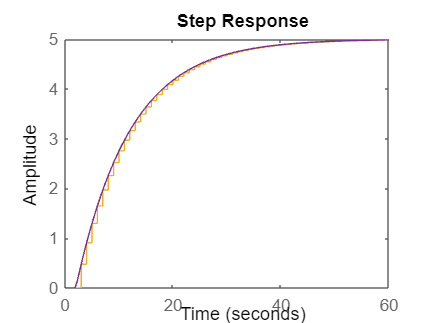

step(Gps)

Caso 1. Deadbeat


$$G_c \left(z\right)=\left(\frac{1}{G_p \left(z\right)}\right)\left(\frac{1}{z^k -1}\right)$$



$$k\ge 3$$


k = 3;
Gcz = 1/(Gpz*(z^k - 1))

Gcz =
 
   z^3 - 0.9048 z^2
  -------------------
  0.4758 z^3 - 0.4758
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Caso 2. PID (Criterios Integrales$\to$ITAE)


$$G_c \left(z\right)=K_{\textrm{pz}} +\frac{K_{\textrm{iz}} }{1-z^{-1} }+K_{\textrm{dz}} \left(1-z^{-1} \right)$$



$$k\ge 3$$


a = 0.965;
b = -0.85;
c = 0.796;
d = -0.147;
e = 0.308;
f = 0.929;


$$G_p \left(s\right)=\frac{{Ke}^{-\theta s} }{\tau s+1}$$


tau = 10;
K = 5

K = 5


Kp = (1/K) * (a*(theta/tau)^b)

Kp = 0.7580

Taui = (tau) / (c + d*(theta/tau))

Taui = 13.0446

Taud = (tau) * (e * (theta/tau)^f)

Taud = 0.6906


Kpz = Kp - (Kp * T)/(2*Taui)

Kpz = 0.7290

Kiz = (Kp*T)/Taui

Kiz = 0.0581

Kdz = (Kp*Taud)/T

Kdz = 0.5235


T = 1

T = 1

z = tf('z',T);
Gpz = 0.4758/(z-0.9048)*z^-2

Gpz =
 
       0.4758
  ----------------
  z^3 - 0.9048 z^2
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


k = 3;
Gcz = 1/(Gpz*(z^k - 1))

Gcz =
 
   z^3 - 0.9048 z^2
  -------------------
  0.4758 z^3 - 0.4758
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Gpz_num = Gpz.Numerator{1,1};
Gpz_den = Gpz.Denominator{1,1};

Caso 3. Controlador de Dahlin


$$G_c \left(z\right)=\left(\frac{1}{G_p \left(z\right)}\right)\left(\frac{T\left(z\right)}{1-T\left(z\right)}\right)$$


Requerimiento (dinámica de primer orden):


$$T\left(s\right)=\frac{1}{\tau s+1}e^{-\textrm{Ls}}$$



$$L=\textrm{kT}$$



$$\tau =2$$


Transformación de tiempo muerto:


$$Z\left\lbrace e^{-\textrm{Ls}} \right\rbrace =z^{-k}$$


Ts = tf([1],[2,1])

Ts =
 
     1
  -------
  2 s + 1
 
Continuous-time transfer function.
Model Properties


Tz = c2d(Ts,T,'zoh')*(z^-k)

Tz =
 
       0.3935
  ----------------
  z^4 - 0.6065 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties



k = 2;
Gcz = (1/Gpz)*(Tz/(1-Tz))

Gcz =
 
              0.3935 z^7 - 0.5947 z^6 + 0.2159 z^5
  -------------------------------------------------------------
  0.4758 z^8 - 0.5772 z^7 + 0.175 z^6 - 0.1872 z^4 + 0.1136 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Gcz_num_dahlin = Gcz.Numerator{1,1};
Gcz_den_dahlin = Gcz.Denominator{1,1};